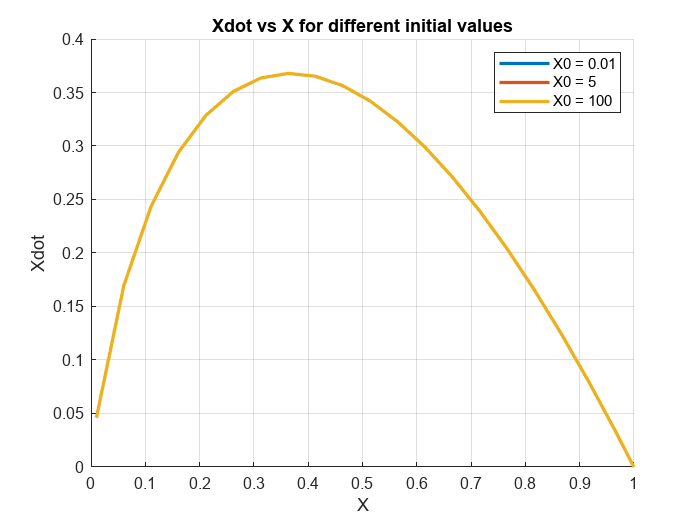

% Define initial values
X0_list = [0.01, 5, 100];

% Plot Xdot vs X for different initial values
figure;
hold on;
for i = 1:length(X0_list)
    X0 = X0_list(i);
    X = linspace(0.01, 5, 100);
    X_dot = -X .* log(X);
    plot(X, X_dot, 'DisplayName', ['X0 = ', num2str(X0)],LineWidth=1);
end

% Label and show the plot
xlabel('X');
ylabel('Xdot');
title('Xdot vs X for different initial values');
ylim([0 0.4]);
xlim([0 1]);
legend();
grid on;
hold off;

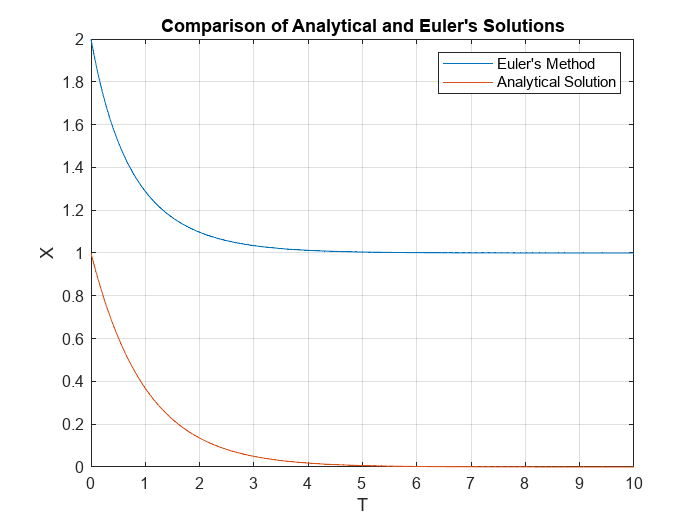


% Define parameters
X0 = 2;
T_final = 10;
delta_t = 0.01;

% Initialize arrays
T = 0:delta_t:T_final;
X_euler = zeros(size(T));
X_euler(1) = X0;

% Perform Euler integration
for i = 2:length(T)
    X_euler(i) = X_euler(i-1) + delta_t .* gompertz_rescaled(X_euler(i-1));
end

% Plot analytical and Euler's solution

plot(T, X_euler, 'DisplayName', 'Euler''s Method');
hold on;
X_analytical = exp(-T);
plot(T, X_analytical, 'DisplayName', 'Analytical Solution');
xlabel('T');
ylabel('X');
title('Comparison of Analytical and Euler''s Solutions');
legend();
grid on;
hold off;

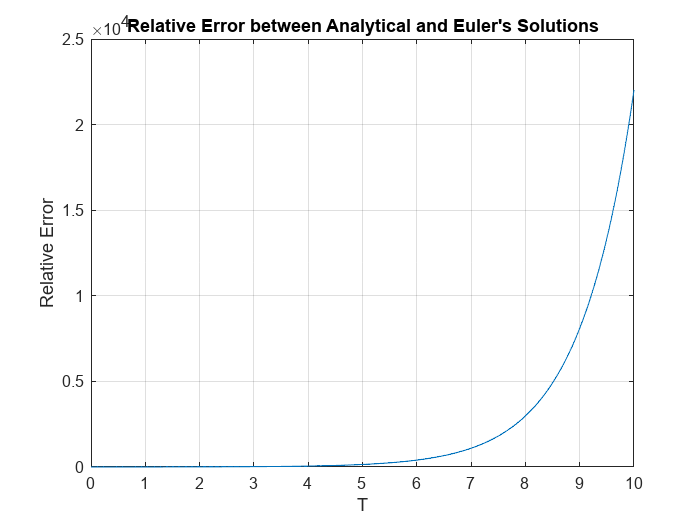



% Calculate relative error
relative_error = abs(X_analytical - X_euler) ./ X_analytical;

% Plot relative error
figure;
plot(T, relative_error);
xlabel('T');
ylabel('Relative Error');
title('Relative Error between Analytical and Euler''s Solutions');
grid on;

function dXdt = gompertz_rescaled(X)
    dXdt = -X * log(X);
end
